An end-to-end communication system 

1. Read signal sound_file.wav and obtain message signal s. Apply Fast Fourier Transform to message signal s and obtain S. Plot frequency magnitude spectrum.

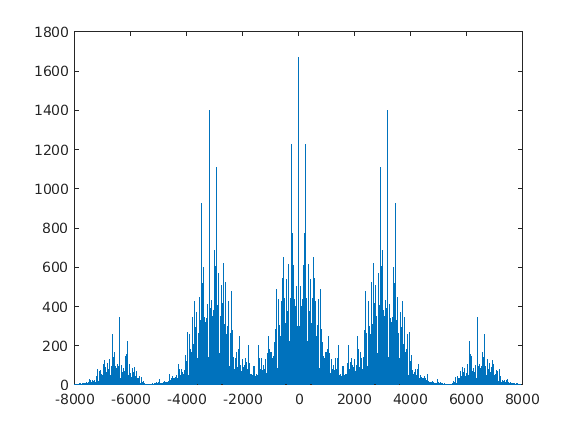

[s,fs] = audioread("sound_file.wav");
S = fft(s);
n = length(s);
c = (-1 * fs) / 2:fs / n:fs / 2 - fs / n; % It generates the frequency series to plot X in frequency domain
plot(c',fftshift(abs(S))); 

2. Filter message signal with cutoff frequency 1500 Hz to obtain filtered signal sf. Plot filtered signal. Apply Fast Fourier Transform to filtered signal and obtain 𝑆𝑓 (𝑗𝜔). Plot the frequency magnitude spectrum.

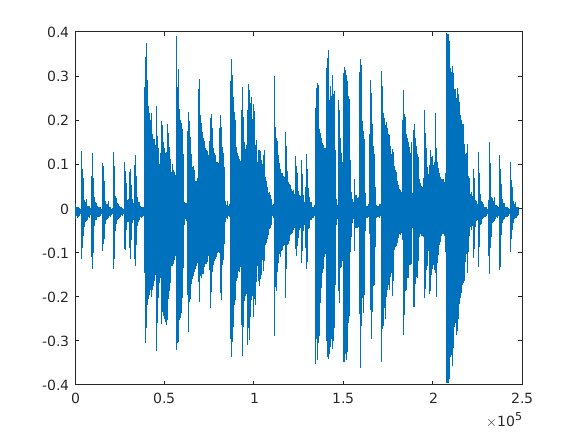

sf = my_LPF(s,fs,1500);
plot(sf)

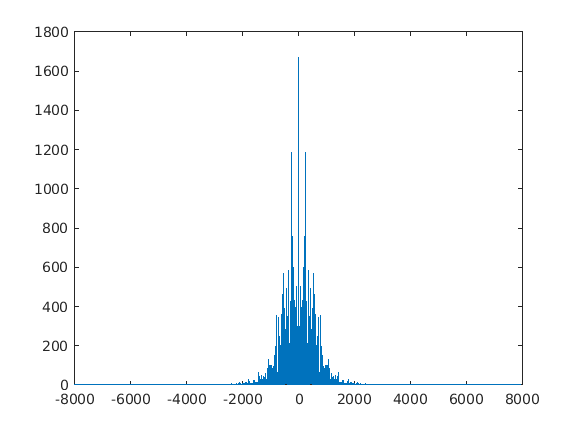

Sf = fft(sf);
n = length(sf);
c = (-1 * fs) / 2:fs / n:fs / 2 - fs / n; 
plot(c',fftshift(abs(Sf))); 

3. Modulate filtered signal with the amplitude modulation to obtain sm. Average power of modulated signal must be normalized.

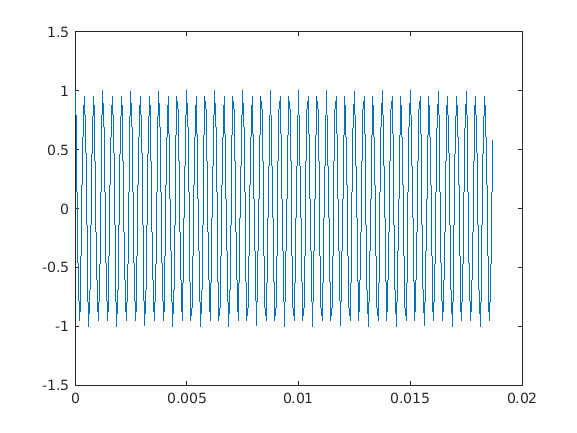

sf = sf / sqrt(sum( sf.^2 )); %Normalizing average power
sm = my_ampmod(sf',15000);
t = (0:1/fs:0.1-1/fs);
plot(t(1:300),sm(1:300))

4.Demodulate modulated signal sm to obtain sd using envelope detector. Plot the demodulated signal.

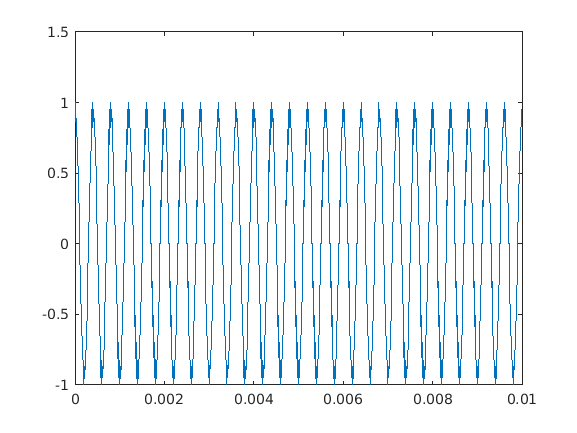

t=[0:1000]*1e-5;
sd = my_env(sm,15000);
plot(t(1:1000),sd(1:1000))

5. Filter demodulated signal with cutoff frequency 1500 Hz to obtain reconstructed signal sr. Plot filtered signal. Apply Fast Fourier Transform to filtered signal and obtain 𝑆𝑟 (𝑗𝜔). Plot frequency spectrum.

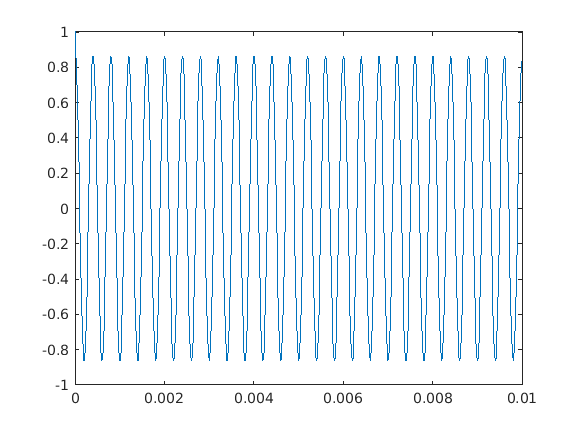

sr = my_LPF(sd,fs,1500);
plot(t(1:1000),sr(1:1000))

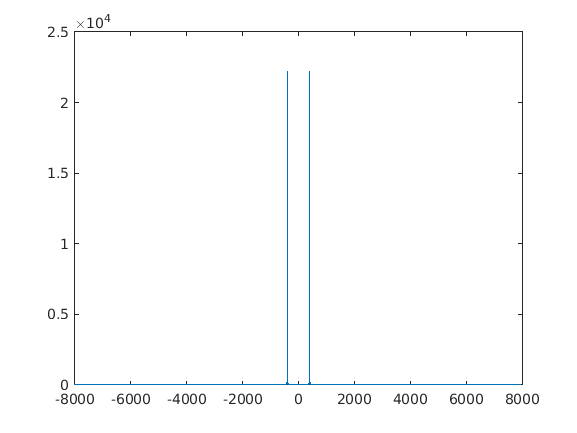

Sr=fft(sr);
n = length(sr);
c = (-1 * fs) / 2:fs / n:fs / 2 - fs / n; 
plot(c',fftshift(abs(Sr))); 